% which_band=1:4
% emotion_data_reconstruction_before_CNN

% cd D:\Documents\emotion_data\Emotion_analysis_all_cream
cd D:\Documents\emotion_data\Emotion_analysis_all_cream\no_noise_remove
load('negative_class_bands_chan2_all_subj.mat')
load('positive_class_bands_chan2_all_subj.mat')

%%%%%%% Define layers and hyper-parameter %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
inputSize=[10 10 1];
size(inputSize);
layers = [
    imageInputLayer(inputSize,'Normalization',  'none','name','input')
    convolution2dLayer([2],10,'Padding','same','name','conv1')
    eluLayer('name','elu1')
    convolution2dLayer([2], 10,'Padding','same','name','conv2')
    eluLayer('name','elu2')
    convolution2dLayer([3], 10,'Padding','same','name','conv3')
    eluLayer('name','elu3')
    convolution2dLayer([3], 10,'Padding','same','name','conv4')
    eluLayer('name','elu4')
    convolution2dLayer([3], 10,'Padding','same','name','conv5')
    eluLayer('name','elu5')
%     dropoutLayer('name','drop')
    fullyConnectedLayer(2,'name','fc')
    softmaxLayer('name','sftmax')
    classificationLayer('name','classfy') ];
lgraph = layerGraph(layers);

miniBatchSize=128

miniBatchSize = 128

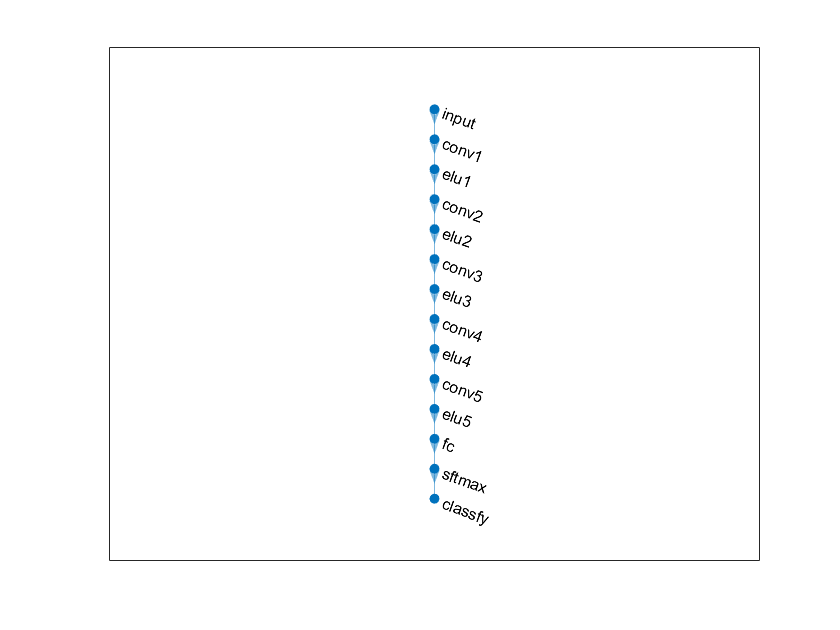

figure;plot(lgraph)

tic
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

subj_POS2=positive_class_bands_chan2_all_subj;
subj_negative2=negative_class_bands_chan2_all_subj;

% accuracy2=[];
% F1_score2=[];
% AUC2=[];
% % probability_pos_class2=[ ];
% % probability_neg_class2=[ ];
% %    conMat2=[];

% for t=1
%                 for t=1
p=1;

%     accuracy4=[];
%     F1_score4=[];
%     probability_pos_class=[ ];
%     probability_neg_class=[ ];
%     accuracy=[];
Result3=[];
% %
% AUC2_val=[];
Result3_val=[];
Result3_max_val_acc=[];
Result3_min_val_loss=[];
for kk=1:length( subj_POS2)
%     for kk=16
    Result1=[];
    Result1_max_val_acc=[];
    Result1_min_val_loss=[];
    Result1_val=[];
    pair_of_validation_test_set=[];
    for kkk=1:length( subj_POS2)-1
%         for kkk=1
        %             for kk=[1:3,5:13,15,16]
        
        subj_POS3=subj_POS2;
        subj_negative3=subj_negative2;
        
        
        validation_subj_POS=subj_POS2{kk};
        validation_subj_negative=subj_negative2{kk};
        %%%%%%%%%%%%% test data %%%%%%%%%%%%%%%%%
        %         tmp_subj=[1:3,5:13,15,16];
        
        tmp_subj=[1:length( subj_POS2)];
        tmp_subj(find(tmp_subj==kk))=[];
        
        kk_test=tmp_subj(kkk);
        test_subj_POS=subj_POS2{kk_test};
        test_subj_negative=subj_negative2{kk_test};
        subj_POS3([kk,kk_test])=[];
        subj_negative3([kk,kk_test])=[];
        pair_of_validation_test_set=[ pair_of_validation_test_set; [kk,kk_test]];
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        size(validation_subj_POS);
        size(validation_subj_negative);
        
        %         subj_POS3(kk)=[];
        %         subj_negative3(kk)=[];
        YTrain=[];
        tmp_POS1=[];
        YTrain_POS_all_subj=[];
        for i=1:length(subj_POS3)
            tmp_POS1 =cat(4,tmp_POS1, subj_POS3{i}) ;
            %         tmp_NEG1 =cat(4,tmp_NEG1,subj_negative3{i}) ;
            YTrain_POS=[];
            if isempty(subj_POS3{i})==0
                for j=1:size( subj_POS3{i},4)
                    YTrain_POS =[YTrain_POS ;categorical(cellstr('POS'))];
                end
            end
            YTrain_POS_all_subj=[YTrain_POS_all_subj; YTrain_POS];
        end
        size(tmp_POS1 );
        
        tmp_NEG1=[];
        YTrain_NEG_all_subj=[];
        for i=1:length(subj_negative3)
            tmp_NEG1 =cat(4,tmp_NEG1, subj_negative3{i}) ;
            %         tmp_NEG1 =cat(4,tmp_NEG1,subj_negative3{i}) ;
            YTrain_NEG=[];
            for j=1:size( subj_negative3{i},4)
                YTrain_NEG =[YTrain_NEG ;categorical(cellstr('NEG'))];
            end
            YTrain_NEG_all_subj=[YTrain_NEG_all_subj; YTrain_NEG];
        end
        YTrain=[YTrain_POS_all_subj;YTrain_NEG_all_subj];
        categories(YTrain);
         %%%%%% randomize train dataset lables   %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        %             YTrain2=YTrain;
        %             YTrain2(randperm(length(YTrain),length(YTrain)))=YTrain;
        %             YTrain=YTrain2;
        
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        
        LOOCV_subj_POS_NEG2=cat(4,tmp_POS1,tmp_NEG1);
        size(LOOCV_subj_POS_NEG2);
        LOOCV_subj_POS_NEG4=LOOCV_subj_POS_NEG2;
        % figure;plot(squeeze(LOOCV_subj_POS_NEG4(3,15,1,:)))
        tmp= size(LOOCV_subj_POS_NEG4);
        numFeatures=1;
        numObservations = length(LOOCV_subj_POS_NEG4);
        % inputSize = size(negative_class_bands_chan_bl2(:,:,:,1));
        XTrain = LOOCV_subj_POS_NEG4;
        %     XTrain=uint8(LOOCV_subj_POS_NEG4)
        
        train_size=size(XTrain);
        % Convert the classes to a vector of categorical labels.
        numClasses = 2;
        
        
        size(YTrain);
        %%%%%%%%%%%%%%%%%%%%%% training data randomize %%%%%%%%%%%%%%%%%%%%%%%%%%%
       
        rand_order=randperm(size(XTrain,4),size(XTrain,4));
        XTrain(:,:,:,rand_order)=XTrain;
         YTrain(rand_order)=YTrain;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        tmp_sign_val=0;
        
        YValidation=[];
        if isempty(validation_subj_POS)==0
            for i=1:size(validation_subj_POS,4)
                YValidation =[YValidation ;categorical(cellstr('POS'))];
            end
        else
            YValidation =[YValidation;categorical(cellstr('POS'))];
            validation_subj_POS(:,:,:,1)=validation_subj_negative(:,:,:,1);
            tmp_sign_val=3;
        end
        
        if isempty(validation_subj_negative)==0
            for i=1:size(validation_subj_negative,4)
                YValidation =[YValidation ;categorical(cellstr('NEG'))];
            end
        else
            YValidation =[YValidation;categorical(cellstr('NEG'))];
            validation_subj_negative(:,:,:,1)=  validation_subj_POS(:,:,:,1);
            tmp_sign_val=4;
        end
        
        
        categories(YValidation );
        
        LOOCV_validation_subj_POS_NEG2 = cat(4,validation_subj_POS,validation_subj_negative);
        
        
        numFeatures=1;
        
        
        XValidation = LOOCV_validation_subj_POS_NEG2;
        
        
            %%%%%%%%%%%%%%%%%%%%%%validation data randomize %%%%%%%%%%%%%%%%%%%%%%%%%%%
%         XValidation1=XValidation;
%           rand_order=randperm(size(XValidation,4)/2,size(XValidation,4)/2);
%         XValidation1(:,:,:,rand_order)=XValidation(:,:,:,rand_order+size(XValidation,4)/2);
%          XValidation1(:,:,:,rand_order+size(XValidation,4)/2)=XValidation(:,:,:,rand_order);
%      XValidation=XValidation1;
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
      
        
        validation_size=size(XValidation);
        cd 'D:\Documents\emotion_data\Emotion_analysis_all_cream\save_network_merged_no_noiseremove' 
        mkdir(['Merged_valiation__' num2str(kk) '__test__' num2str(kk_test)])
        cd (['Merged_valiation__' num2str(kk) '__test__' num2str(kk_test)])
        delete *.mat
       currentFolder = pwd;
      
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
 
        checkpointPath =currentFolder;
        validationFrequency = floor(numel(YTrain)/miniBatchSize);
        %                 validationFrequency =10;
       options = trainingOptions('adam' , ...
            'InitialLearnRate',0.0002, ...
            'Shuffle','every-epoch', ...
            'MaxEpochs',300, ...
            'MiniBatchSize',miniBatchSize, ....
            'ValidationData',{XValidation,YValidation}, ...
            'Verbose',false,...
             'CheckpointPath' ,checkpointPath,...
             'ValidationFrequency',validationFrequency);
%        ,...
%             'CheckpointPath' ,checkpointPath);
%              'Verbose',false,...
%        , ...
%             'Plots','training-progress', ...
%             , ...
%              'L2Regularization',0.05);
%             'Plots','training-progress', ...
%               'L2Regularization',0.05, ...
         %              'LearnRateDropFactor' , 0.1,...
%             'LearnRateDropPeriod' , 10,...
            %             'LearnRateDropFactor' , 0.1,...
%             'LearnRateDropPeriod' , 10,...
%               'CheckpointPath' ,checkpointPath);
%             'OutputFcn',@(info)stopIfAccuracyNotImproving(info,2));
        %             'Plots','training-progress', ...
        %        'GradientDecayFactor',0.95,...
        %          'LearnRateSchedule' , 'piecewise' ,...
        %             'LearnRateDropFactor' ,0.1,...
        %             'LearnRateDropPeriod' , 20,...
        %             'GradientDecayFactor',0.9,...
        % Train the network using trainNetwork.
        [net1,info] = trainNetwork(XTrain,YTrain,lgraph,options);
       
         checkpoints_find_validation_maximum_accuracy_point
        
       save('info.mat', 'info', '-v7.3')
       save('net1.mat', 'net1', '-v7.3')
      
   %%%%%%%%%%%%%%%%%%%%%%%% Test %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        tmp_sign=0;
        YTest=[];
        if isempty(test_subj_POS)==0
            for i=1:size(test_subj_POS,4)
                YTest =[YTest ;categorical(cellstr('POS'))];
            end
        else
            YTest =[YTest;categorical(cellstr('POS'))];
            test_subj_POS(:,:,:,1)=test_subj_negative(:,:,:,1);
            tmp_sign=1;
        end
        
        if isempty(test_subj_negative)==0
            for i=1:size(test_subj_negative,4)
                YTest =[YTest ;categorical(cellstr('NEG'))];
            end
        else
            YTest =[YTest;categorical(cellstr('NEG'))];
            test_subj_negative(:,:,:,1)=  test_subj_POS(:,:,:,1);
            tmp_sign=2;
        end
        
        
        categories(YTest );
        
        LOOCV_test_subj_POS_NEG2 = cat(4,test_subj_POS,test_subj_negative);
        
        
        numFeatures=1;
        
        
        %         XValidation = LOOCV_validation_subj_POS_NEG2;
        
        %         validation_size=size(XValidation);
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        
        %         LOOCV_test_subj_POS_NEG2=LOOCV_validation_subj_POS_NEG2;
        
        size(LOOCV_test_subj_POS_NEG2);
        numFeatures=1;
        
        
        XTest = LOOCV_test_subj_POS_NEG2;
        
        test_size=size(XTest);
        
        YPred=[];
        [YPred, error] = classify(find_max_validation_acc_net.net,XTest);
%               [YPred, error] = classify(net1,XTest);
        %%%%%%%%%%%%%%%%%%%%%%%%% median filter %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        YPred_double= double(YPred);
        YPred1=YPred;
        y = medfilt1( YPred_double,7);
        YPred1(find(y==1))=categorical(cellstr('POS'));
        YPred1(find(y==2))=categorical(cellstr('NEG'));
        YPred=YPred1;
%         
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %             L = predict(net,XTest);
        if  tmp_sign==1
            YPred(1)={'POS'};
        elseif  tmp_sign==2
            YPred(1)={'NEG'};
        end
        
        if std(double(YPred))==0
            if double(YPred(1))==1
                YPred(1)={'NEG'};
            else
                YPred(1)={'POS'};
            end
        end
        
        conMat= confusionmat(YTest,YPred);
        %         plotconfusion(YTest,YPred);title(['Subject ' num2str(kk)])
        TP=conMat(1,1);
        TN=conMat(2,2);
        FN=conMat(1,2);
        FP=conMat(2,1);
        
        sensitivity=TP/(TP+FN);
        specificity=TN/(TN+FP);
        accuracy=(TP+TN)/(TP+TN+FP+FN);
        
        
        cgt = double(YTest); clabel = double(YPred);
        cscores = double(error);
        
%         [X,Y,T,AUC] = perfcurve(cgt,(cscores(:,1)),1);
%         %            figure;
%         plot(X,Y,'k');
%         AUC;
        
    
        if length(find(double(YTest)==1))==1
            YTest(length(YTest)+1:length(YTest)+length(find(double(YTest)==2))-1)={'POS'};
            YPred(length(YPred)+1:length(YTest))={'POS'};
            error([length(error(:,1))+1:length(YTest)],:)=repmat([1 0],[length(YTest)-length(clabel) 1]);
        end
        [c_matrix,Result]=confusion.getMatrix(double(YTest), double(YPred),error,0);
         Result.find_epoch_max_acc= fix(str2num(find_epoch_max_acc)/validationFrequency)+1;
        Result1_max_val_acc{kkk}= Result;
        p

         YPred=[];
        [YPred, error] = classify(find_min_validation_loss_net.net,XTest);
        
        %%%%%%%%%%%%%%%%%%%%%%%%% median filter %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        YPred_double= double(YPred);
        YPred1=YPred;
        y = medfilt1( YPred_double,7);
        YPred1(find(y==1))=categorical(cellstr('POS'));
        YPred1(find(y==2))=categorical(cellstr('NEG'));
        YPred=YPred1;
%         
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
        %             L = predict(net,XTest);
        if  tmp_sign==1
            YPred(1)={'POS'};
        elseif  tmp_sign==2
            YPred(1)={'NEG'};
        end
        
        if std(double(YPred))==0
            if double(YPred(1))==1
                YPred(1)={'NEG'};
            else
                YPred(1)={'POS'};
            end
        end
        
        conMat= confusionmat(YTest,YPred);
        %         plotconfusion(YTest,YPred);title(['Subject ' num2str(kk)])
        TP=conMat(1,1);
        TN=conMat(2,2);
        FN=conMat(1,2);
        FP=conMat(2,1);
        
        sensitivity=TP/(TP+FN);
        specificity=TN/(TN+FP);
        accuracy=(TP+TN)/(TP+TN+FP+FN);
        
        
        cgt = double(YTest); clabel = double(YPred);
        cscores = double(error);
        
%         [X,Y,T,AUC] = perfcurve(cgt,(cscores(:,1)),1);
%         %            figure;
%         plot(X,Y,'k');
%         AUC;
        
    
        if length(find(double(YTest)==1))==1
            YTest(length(YTest)+1:length(YTest)+length(find(double(YTest)==2))-1)={'POS'};
            YPred(length(YPred)+1:length(YTest))={'POS'};
            error([length(error(:,1))+1:length(YTest)],:)=repmat([1 0],[length(YTest)-length(clabel) 1]);
        end
        [c_matrix,Result]=confusion.getMatrix(double(YTest), double(YPred),error,0);
       
         Result.find_epoch_min_loss= fix(str2num(find_epoch_min_loss)/validationFrequency)+1;
        Result1_min_val_loss{kkk}= Result;
            p=p+1;
      
    end

    Result3_max_val_acc=[Result3_max_val_acc ;Result1_max_val_acc];
    Result3_min_val_loss=[Result3_min_val_loss ;Result1_min_val_loss];
end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

cd D:\Documents\emotion_data\Emotion_analysis_all_cream\no_noise_remove_results
 save Result3_min_val_loss_merged_no_drop.mat Result3_min_val_loss
save Result3_max_val_acc_merged_no_drop.mat Result3_max_val_acc

